# 6.3 脉冲响应不变法：z=e^{sT} 的映射、部分分式变换（例 6.4）、频率响应混叠、例 6.5 的完整设计

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。变换自写（dsp_impinvar：residue + 极点映射），有工具箱时与 impinvar 对照。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if ~exist(fullfile(here, 'dsp_freqz.m'), 'file'), here = fileparts(which('dsp_freqz')); end   % Live Script 里 mfilename 为空时靠路径找
codedir = here; addpath(codedir); outdir = fullfile(codedir, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：z=e^{sT}：s 平面每条宽 2π/T 的横带都映到整个 z 平面——不是一一对应（教材图 6.2.2）

T = 1; sig = [-1.5 -1 -0.5 0]; Om = linspace(-pi/T, pi/T, 25);
[S, O] = meshgrid(sig, Om); s0 = S + 1i*O;                            % 主带 |Ω|≤π/T
s1 = s0 + 2i*pi/T; s2 = s0 - 2i*pi/T;                                 % 相邻两条带
z0 = exp(s0*T); z1 = exp(s1*T); z2 = exp(s2*T);
errStrip = max(abs([z1(:) - z0(:); z2(:) - z0(:)]));                  % 三条带映到同一批点

## 演示2：例 6.4：Ha(s)=(s+1)/(s²+5s+6)，T=1：部分分式 → 每个极点 s_i → e^{s_i T}（教材式 (6.2.6)）

b = [1 1]; a = [1 5 6]; w = linspace(0, pi, 512);
[bz, az, r, p] = dsp_impinvar(b, a, 1);                               % r=[2;−1]，p=[−3;−2]
bzBook = [1 -0.2208835]; azBook = [1 -0.18512235 0.00673795];
errBook = max(abs([bz - bzBook, az - azBook]));
n = 0:24; ha = -exp(-2*n) + 2*exp(-3*n);                              % ha(t)=−e^{−2t}+2e^{−3t}，取 t=nT
hd = filter(bz, az, [1 zeros(1, numel(n)-1)]); errH = max(abs(hd - ha));
errSPT = NaN; if exist('impinvar', 'file') == 2, [bI, aI] = impinvar(b, a, 1); errSPT = max(abs([bI - bz, aI - az])); end   % 工具箱版可能含 h_a(0+)/2 修正
% 注意：例 6.4 的 h_a(t) 在 t=0 有跳变（分子阶数 = 分母阶数 − 1，h_a(0+)=1）。按式 (6.2.1) 的周期延拓之和对应 h(0)=h_a(0+)/2，
% 而教材/residue 做法取 h(0)=h_a(0+)，两者的频率响应差一个常数 h_a(0+)/2=0.5（Jackson 2000 的“脉冲响应不变法修正”）。
acc64 = zeros(size(w)); for m = -2000:2000, acc64 = acc64 + dsp_freqs(b, a, w + 2*pi*m); end
jumpOffset = max(abs(dsp_freqz(bz, az, w) - acc64 - 0.5));

## 演示3：频率响应是 Ha(jΩ) 的周期延拓之和（教材式 (6.2.1)(6.2.2)）：Ha 不带限，T 越大混叠越重

用 h_a(t) 在 t=0 连续的 Ha(s)=6/(s²+5s+6)（M<N−1），避免上面的跳变项干扰

b3 = 6; a3 = [1 5 6]; Ts = [1 0.2];
Hd = zeros(2, numel(w)); Hsum = Hd; Hone = Hd;
for i = 1:2
    Ti = Ts(i); [bt, at] = dsp_impinvar(b3, a3, Ti);
    Hd(i, :) = dsp_freqz(bt, at, w);                                   % 数字滤波器的 H(e^{jω})
    Hone(i, :) = dsp_freqs(b3, a3, w/Ti)/Ti;                           % 只取 m=0 一项：(1/T)Ha(jω/T)
    acc = zeros(size(w)); for m = -2000:2000, acc = acc + dsp_freqs(b3, a3, (w + 2*pi*m)/Ti); end
    Hsum(i, :) = acc/Ti;                                               % 全部周期延拓之和
end
errSum = max(abs(Hd - Hsum), [], 2).';                                 % 应为 0：式 (6.2.1) 成立
aliasRel = max(abs(Hd - Hone), [], 2).' ./ max(abs(Hd), [], 2).';     % 混叠相对大小

## 演示4：例 6.5 的完整设计：巴特沃思 N=6、Ωc=0.7032 → 脉冲响应不变法（T=1）→ 三个二阶节 → 核对指标

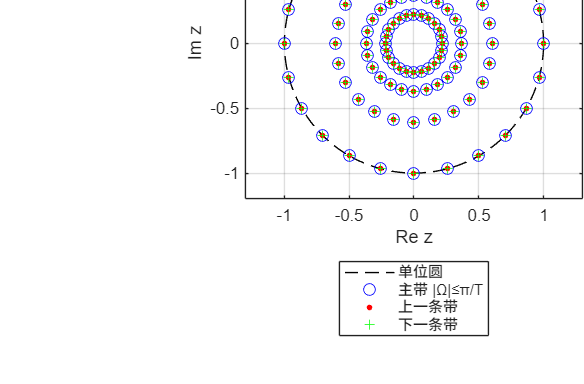

Wp = 0.2*pi; Ws = 0.3*pi; ap = 1; as = 15;
N = 6; Wc = Wp/(10^(ap/10) - 1)^(1/(2*N));
[bA, aA, pA] = dsp_butter_analog(N, Wc);
[bz5, az5, r5, p5] = dsp_impinvar(bA, aA, 1);
% 共轭对合并成二阶节：r/(1−pz⁻¹)+r*/(1−p*z⁻¹) = [2Re r − 2Re(r p*) z⁻¹] / [1 − 2Re p z⁻¹ + |p|² z⁻²]
p5 = exp(p5*1);                                                         % 模拟极点 s_i → 数字极点 e^{s_i T}
[~, order] = sort(imag(p5)); p5 = p5(order); r5 = r5(order);          % 让共轭对相邻
secNum = zeros(3, 2); secDen = zeros(3, 3); k = 0;
for i = find(imag(p5) > 1e-9).'
    k = k + 1; pk = p5(i); rk = r5(i);
    secNum(k, :) = [2*real(rk), -2*real(rk*conj(pk))]; secDen(k, :) = [1, -2*real(pk), abs(pk)^2];
end
[~, o2] = sort(secDen(:, 2)); secNum = secNum(o2, :); secDen = secDen(o2, :);
denBook = [1 -1.2971 0.6949; 1 -1.0691 0.3699; 1 -0.9972 0.2570]; numBook = [0.2871 -0.4466; -2.1428 1.1455; 1.8558 -0.6304];
errSec = max(abs([secDen - denBook, secNum - numBook]), [], 'all');
H5 = dsp_freqz(bz5, az5, w); H50 = abs(dsp_freqz(bz5, az5, 0));
attP = -20*log10(abs(dsp_freqz(bz5, az5, Wp))/H50); attS = -20*log10(abs(dsp_freqz(bz5, az5, Ws))/H50);
HA = dsp_freqs(bA, aA, w);                                             % 模拟原型（T=1 时 Ω=ω）

if ~LIVE, f1 = figure('Name','03 脉冲响应不变法','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); tt = linspace(0, 2*pi, 400); plot(cos(tt), sin(tt), 'k--'); hold on; axis equal; grid on;
plot(real(z0(:)), imag(z0(:)), 'bo', 'MarkerSize', 7); plot(real(z1(:)), imag(z1(:)), 'r.', 'MarkerSize', 10); plot(real(z2(:)), imag(z2(:)), 'g+', 'MarkerSize', 6);
xlim([-1.3 1.3]); ylim([-1.2 1.2]); xlabel('Re z'); ylabel('Im z');
title(sprintf('① z=e^{sT}：s 平面三条相邻横带映到同一批点（差 %.0e）', errStrip));
legend('单位圆', '主带 |Ω|≤π/T', '上一条带', '下一条带');

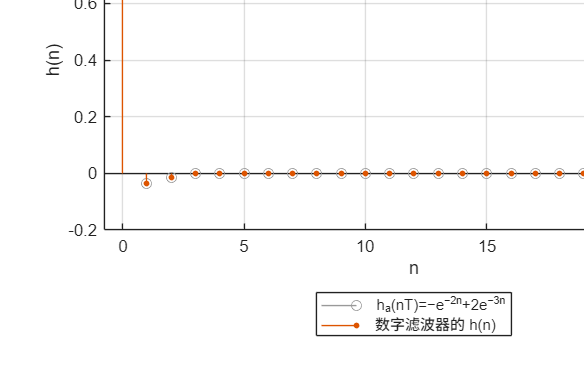

newpanel(); stem(n, ha, 'MarkerSize', 6, 'Color', [0.6 0.6 0.6]); hold on; stem(n, hd, 'filled', 'MarkerSize', 3);
grid on; xlabel('n'); ylabel('h(n)');
title(sprintf('② 例 6.4：H(z)=(1−%.4fz^{−1})/(1−%.4fz^{−1}+%.5fz^{−2})，h(n)=h_a(nT)', -bz(2), -az(2), az(3)));
legend('h_a(nT)=−e^{−2n}+2e^{−3n}', '数字滤波器的 h(n)');

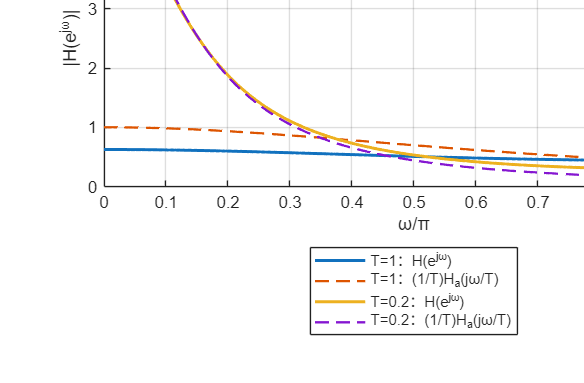

newpanel(); plot(w/pi, abs(Hd(1, :)), 'LineWidth', 1.8); hold on; plot(w/pi, abs(Hone(1, :)), '--', 'LineWidth', 1.4);
plot(w/pi, abs(Hd(2, :)), 'LineWidth', 1.8); plot(w/pi, abs(Hone(2, :)), '--', 'LineWidth', 1.4);
grid on; xlabel('ω/π'); ylabel('|H(e^{jω})|');
title(sprintf('③ H_a=6/(s²+5s+6)：H(e^{jω}) 与单项 (1/T)H_a(jω/T) 的差，T=1 为 %.0f%%，T=0.2 为 %.1f%%', 100*aliasRel(1), 100*aliasRel(2)));
legend('T=1：H(e^{jω})', 'T=1：(1/T)H_a(jω/T)', 'T=0.2：H(e^{jω})', 'T=0.2：(1/T)H_a(jω/T)');

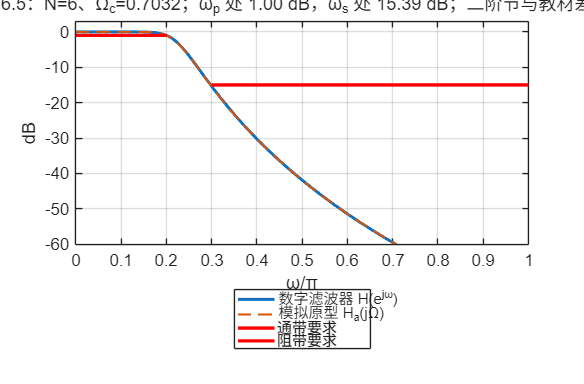

newpanel(); plot(w/pi, 20*log10(abs(H5)/H50), 'LineWidth', 1.8); hold on; plot(w/pi, 20*log10(abs(HA)), '--', 'LineWidth', 1.2);
plot([0 Wp/pi], [-ap -ap], 'r-', 'LineWidth', 2); plot([Ws/pi 1], [-as -as], 'r-', 'LineWidth', 2);
grid on; ylim([-60 3]); xlabel('ω/π'); ylabel('dB');
title(sprintf('④ 例 6.5：N=6、Ω_c=%.4f；ω_p 处 %.2f dB，ω_s 处 %.2f dB；二阶节与教材差 %.0e', Wc, attP, attS, errSec));
legend('数字滤波器 H(e^{jω})', '模拟原型 H_a(jΩ)', '通带要求', '阻带要求');

if ~LIVE, sgtitle('脉冲响应不变法：h(n)=h_a(nT)，极点 s_i→e^{s_iT}；频率响应是 H_a 的周期延拓之和，只适合带限的低通、带通'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '03-impulse-invariance.png'), 'Resolution', 150); end

## 教师核验

assert(errStrip < 1e-12, '相邻带应映到同一点');
assert(errBook < 1e-6 && errH < 1e-12, '例 6.4 结果不符');
assert(all(errSum < 2e-3) && jumpOffset < 2e-3, '式 (6.2.1) 核验失败');   % 周期延拓截到 |m|≤2000
assert(aliasRel(1) > 5*aliasRel(2), 'T 小时混叠应更轻');
assert(errSec < 2e-3, '例 6.5 二阶节与教材不符');
assert(attP <= ap + 0.05 && attS >= as, '例 6.5 指标核验不符');
% 工具箱 impinvar 与本函数逐系数一致（本机差 3e-15，即它也不做 h_a(0+)/2 修正）
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'ex64_residues', r.', 'ex64_poles', p.', 'ex64_bz', bz, 'ex64_az', az, 'ex64_err_vs_book', errBook, 'ex64_err_h', errH, 'err_vs_impinvar', errSPT, 'ex64_jump_offset_check', jumpOffset, ...
    'T_values', Ts, 'err_sum_formula', errSum, 'alias_relative', aliasRel, ...
    'ex65_Wc', Wc, 'ex65_sec_num', secNum, 'ex65_sec_den', secDen, 'ex65_err_vs_book', errSec, 'ex65_att_wp_dB', attP, 'ex65_att_ws_dB', attS, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-impulse-invariance.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

            matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                    run_at: '2026-09-18 21:31:28'
             ex64_residues: [2.0000 -1.0000]
                ex64_poles: [-3.0000 -2.0000]
                   ex64_bz: [1 -0.2209]
                   ex64_az: [1 -0.1851 0.0067]
          ex64_err_vs_book: 3.0009e-09
                ex64_err_h: 1.3878e-17
           err_vs_impinvar: 0
    ex64_jump_offset_check: 1.2880e-04
                  T_values: [1 0.2000]
           err_sum_formula: [1.5194e-04 3.0389e-05]
            alias_relative: [0.7949 0.0353]
                   ex65_Wc: 0.7032
              ex65_sec_num: [3×2 double]
              ex65_sec_den: [3×3 double]
          ex65_err_vs_book: 7.1112e-05
            ex65_att_wp_dB: 0.9999
            ex65_att_ws_dB: 15.3903
         all_checks_passed: 1


课堂图已保存到：G:\2026-Agent\数字信号处理\课程网站\ch6\code\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end